# 1. Importar e conhecer o ensaio

Executar por seccoes (Ctrl+Enter). Requer os CSV na mesma pasta. Objetivo: selecionar e justificar uma gama de calibracao linear.

clear; clc; close all;
[nome,pasta]=uigetfile('*.csv','Selecionar ensaio_viga_mock.csv');
if isequal(nome,0), disp('Selecao cancelada.'); return; end
T = readtable(fullfile(pasta,'calibracao_mock.csv'));
F = T.Forca_N; V = T.Saida_mV;
disp(T);

    Forca_N    Repeticao    Saida_mV
    _______    _________    ________

       0           1        0.11885 
       0           2        0.11862 
       0           3        0.11911 
       5           1         1.1256 
       5           2          1.119 
       5           3          1.108 
      10           1         2.1227 
      10           2         2.1179 
      10           3         2.1183 
      15           1         3.1209 
      15           2         3.1219 
      15           3         3.1293 
      20           1         4.1253 
      20           2         4.1209 
      20           3         4.1141 
      25           1         5.1119 
      25           2          5.122 
      25           3         5.1305 
      30           1         6.1203 
      30           2         6.1191 
      30           3         6.1243 
      35           1         7.0084 
      35 

## 2. Observar TODOS os dados antes de ajustar

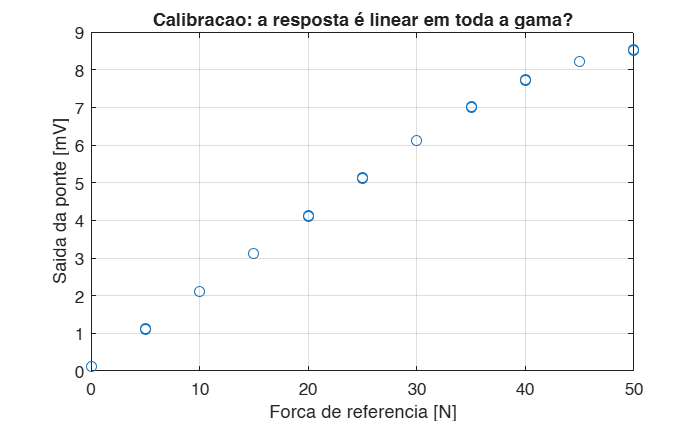

figure('Name','Dados brutos');
plot(F,V,'o'); grid on;
xlabel('Forca de referencia [N]'); ylabel('Saida da ponte [mV]');
title('Calibracao: a resposta é linear em toda a gama?');

## 3. Escolher uma gama candidata

PRIMEIRA EXECUCAO: 50 N. Repetir com 40, 35, 30, 25 e 15 N. Guardar os resultados e comparar os residuos, nao apenas o R2.

Fmax = 50; % ALTERAR ESTE VALOR
usar = F <= Fmax;
assert(numel(unique(F(usar)))>=3,'Selecionar pelo menos 3 niveis de carga.');
p = polyfit(F(usar),V(usar),1); % V = a*F + b
a = p(1); b = p(2);
res = V(usar)-polyval(p,F(usar));
R2 = 1-sum(res.^2)/sum((V(usar)-mean(V(usar))).^2);
RMSE = sqrt(mean(res.^2));
fprintf('Gama 0-%g N: a=%.5f mV/N; b=%.5f mV\n',Fmax,a,b);

Gama 0-50 N: a=0.17630 mV/N; b=0.43918 mV


fprintf('R2=%.6f; RMSE=%.5f mV\n',R2,RMSE);

R2=0.986128; RMSE=0.33061 mV


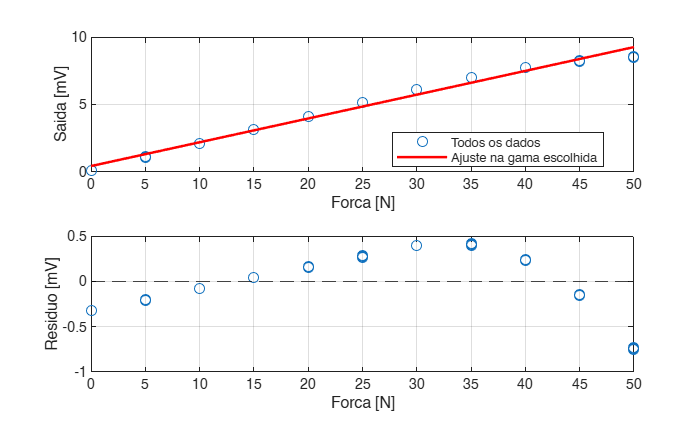

figure('Name','Gama candidata');
subplot(2,1,1);
plot(F,V,'o'); hold on;
plot([0 Fmax],polyval(p,[0 Fmax]),'r-','LineWidth',1.5);
grid on; xlabel('Forca [N]'); ylabel('Saida [mV]');
legend('Todos os dados','Ajuste na gama escolhida','Location','best');
subplot(2,1,2);
plot(F(usar),res,'o'); yline(0,'k--'); grid on;
xlabel('Forca [N]'); ylabel('Residuo [mV]');

## 4. Converter uma leitura de tensao em forca

M = readtable(fullfile(pasta,'medicao_desconhecida.csv'));
Fest = (M.Saida_mV-b)/a;
fprintf('Leitura %.3f mV -> %.3f N\n',M.Saida_mV,Fest);

Leitura 5.320 mV -> 27.685 N


if Fest<min(F(usar)) || Fest>max(F(usar))
    warning('Estimativa fora da gama calibrada: extrapolacao!');
end

## 5. Conclusao a escrever pelos alunos

Indicar: gama escolhida, sensibilidade, offset, RMSE e forca estimada. Justificar com os residuos e a repetibilidade. Uma gama muito curta pode parecer linear, mas limita a utilizacao. Uma reta nao valida leituras fora da gama escolhida.